# Códigos de proyecto

Sección: LAB 41

N.° de grupo: 4

Título: Comparación de esquemas de diferencias finitas para la ecuación del calor con una fuente térmica móvil

Integrante 1 (líder): Keyra Huamanyauri Alvarado — 100 %

Integrante 2: Helen Santillan Socla — 100 %

Integrante 3: Rodolfo Huaroc Enciso — 100 %

## Código 1. Parámetros de la barra y fuente móvil

%% PROYECTO - ETAPA 1: ECUACION DEL CALOR CON FUENTE TERMICA MOVIL
% Curso CC2104 - Metodos Numericos, Grupo 4.
% Crank-Nicolson + Jacobi/Gauss-Seidel y solucion directa de referencia.
% Las tres funciones originales de la plantilla se conservan al final.
clear; clc; close all;
format short g;

%% CODIGO 1. Parametros del modelo y malla
L = 1.0;                 % Longitud (m)
alpha = 1e-4;            % Difusividad termica (m^2/s)
T_0 = 20;                % Temperatura inicial interior (°C)
T_L = 100;               % Temperatura en x=0 (°C)
T_R = 0;                 % Temperatura en x=L (°C)
t_f = 100;               % Tiempo final (s)
N_x = 101;               % Nodos espaciales
dt_solicitado = 0.25;    % Paso temporal (s)
Tol = 1e-8;              % Tolerancia original

% FUENTE TERMICA MOVIL (parametros ilustrativos, no calibrados experimentalmente)
Q0 = 2.0;                % Intensidad maxima efectiva (°C/s)
sigma = 0.05;            % Ancho caracteristico (m)
x_s = 0.10;              % Posicion inicial del centro (m)
v = 0.008;               % Velocidad del centro (m/s)
xc = @(tk) x_s + v*tk;
q = @(xx,tk) Q0*exp(-(xx-xc(tk)).^2/(2*sigma^2));
assert(sigma > 0 && Q0 >= 0, 'Parametros de fuente invalidos.');
assert(min(xc([0,t_f])) >= 0 && max(xc([0,t_f])) <= L, ...
    'El centro de la fuente debe permanecer en la barra.');

x = linspace(0,L,N_x)';
dx = x(2)-x(1);
N_t = round(t_f/dt_solicitado);
dt = t_f/N_t;
t = linspace(0,t_f,N_t+1);
n = N_x-2;
xi = x(2:end-1);
r = alpha*dt/dx^2;
fprintf('CRANK-NICOLSON CON FUENTE TERMICA MOVIL\n');

CRANK-NICOLSON CON FUENTE TERMICA MOVIL


fprintf('dx = %.6g m | dt = %.6g s | r = %.6g\n',dx,dt,r);

dx = 0.01 m | dt = 0.25 s | r = 0.25


fprintf('Fuente: Q0 = %.3f °C/s | sigma = %.3f m | v = %.4f m/s\n',Q0,sigma,v);

Fuente: Q0 = 2.000 °C/s | sigma = 0.050 m | v = 0.0080 m/s


fprintf('Centro de la fuente: %.3f m -> %.3f m\n\n',xc(0),xc(t_f));

Centro de la fuente: 0.100 m -> 0.900 m



## Código 2. Matrices, condiciones iniciales y métricas

%% CODIGO 2. Matrices, condiciones iniciales y metricas
% Solo se discretizan los nodos interiores. Las matrices no cambian al
% introducir una fuente prescrita, independiente de la temperatura.
A = diag((1+r)*ones(n,1)) ...
    + diag((-r/2)*ones(n-1,1),1) ...
    + diag((-r/2)*ones(n-1,1),-1);
B = diag((1-r)*ones(n,1)) ...
    + diag((r/2)*ones(n-1,1),1) ...
    + diag((r/2)*ones(n-1,1),-1);
assert(diagdom(A)==1,'La matriz no es estrictamente diagonal dominante.');

frontera = zeros(n,1);
frontera(1) = frontera(1) + r*T_L;
frontera(end) = frontera(end) + r*T_R;

T_J = T_0*ones(N_x,N_t+1);
T_J(1,:) = T_L; T_J(end,:) = T_R;
T_GS = T_J;
T_ref = T_J;             % CN con fuente, resuelto con A\b
T_sin = T_J;             % CN sin fuente, control fisico
u_J = T_J(2:end-1,1);
u_GS = T_GS(2:end-1,1);
u_ref = T_ref(2:end-1,1);
u_sin = T_sin(2:end-1,1);

iter_J = zeros(N_t,1); iter_GS = zeros(N_t,1);
errorIter_J = zeros(N_t,1); errorIter_GS = zeros(N_t,1);
resRel_J = zeros(N_t,1); resRel_GS = zeros(N_t,1);
tiempo_J = 0; tiempo_GS = 0; tiempo_ref = 0;



## Código 3. Evolución temporal con fuente móvil

%% CODIGO 3. Evolucion temporal con fuente movil
for k = 1:N_t
    % Regla del trapecio para integrar q durante el paso temporal.
    aporte = (dt/2)*(q(xi,t(k)) + q(xi,t(k+1)));

    % Cada solucionador utiliza su propio estado anterior.
    b_J = B*u_J + frontera + aporte;
    b_GS = B*u_GS + frontera + aporte;
    b_ref = B*u_ref + frontera + aporte;
    b_sin = B*u_sin + frontera;

    tic;
    z_J = jacobi(A,b_J,u_J,Tol);
    tiempo_J = tiempo_J + toc;
    u_J = z_J(end,1:n)';
    T_J(2:end-1,k+1) = u_J;
    iter_J(k) = size(z_J,1)-1;
    errorIter_J(k) = z_J(end,end);
    resRel_J(k) = norm(A*u_J-b_J,inf)/max(norm(b_J,inf),1);

    tic;
    z_GS = gausseidel(A,b_GS,u_GS,Tol);
    tiempo_GS = tiempo_GS + toc;
    u_GS = z_GS(end,1:n)';
    T_GS(2:end-1,k+1) = u_GS;
    iter_GS(k) = size(z_GS,1)-1;
    errorIter_GS(k) = z_GS(end,end);
    resRel_GS(k) = norm(A*u_GS-b_GS,inf)/max(norm(b_GS,inf),1);

    tic;
    u_ref = A\b_ref;
    tiempo_ref = tiempo_ref + toc;
    T_ref(2:end-1,k+1) = u_ref;

    % Caso sin aporte movil: aisla el efecto de la fuente termica.
    u_sin = A\b_sin;
    T_sin(2:end-1,k+1) = u_sin;
end



## Código 4. Resultados y comprobaciones

%% CODIGO 4. Resultados y comprobaciones
Diferencia_J_GS = abs(T_J-T_GS);
Incremento_fuente = T_ref-T_sin;
maxErrorRef_J = max(abs(T_J(:)-T_ref(:)));
maxErrorRef_GS = max(abs(T_GS(:)-T_ref(:)));
maxDiferencia_J_GS = max(Diferencia_J_GS(:));
[maxIncremento,idx] = max(Incremento_fuente(:));
[ix,it] = ind2sub(size(Incremento_fuente),idx);
maxT = max(max(T_ref(2:end-1,:)));
errorFrontera = max(abs([T_J(1,:)-T_L, T_J(end,:)-T_R, ...
    T_GS(1,:)-T_L, T_GS(end,:)-T_R, T_ref(1,:)-T_L, T_ref(end,:)-T_R]));

fprintf('RESULTADOS DEL CASO CON FUENTE\n');

RESULTADOS DEL CASO CON FUENTE


fprintf('Iteraciones acumuladas Jacobi:       %d\n',sum(iter_J));

Iteraciones acumuladas Jacobi:       3639


fprintf('Iteraciones acumuladas Gauss-Seidel: %d\n',sum(iter_GS));

Iteraciones acumuladas Gauss-Seidel: 2827


fprintf('Residuo relativo maximo Jacobi:      %.6e\n',max(resRel_J));

Residuo relativo maximo Jacobi:      2.103240e-09


fprintf('Residuo relativo maximo GS:          %.6e\n',max(resRel_GS));

Residuo relativo maximo GS:          9.955188e-10


fprintf('Diferencia maxima J-GS:              %.6e °C\n',maxDiferencia_J_GS);

Diferencia maxima J-GS:              1.047043e-05 °C


fprintf('Diferencia maxima J-directa:         %.6e °C\n',maxErrorRef_J);

Diferencia maxima J-directa:         1.591554e-05 °C


fprintf('Diferencia maxima GS-directa:        %.6e °C\n',maxErrorRef_GS);

Diferencia maxima GS-directa:        6.515879e-06 °C


fprintf('Tiempo Jacobi:                       %.6f s\n',tiempo_J);

Tiempo Jacobi:                       0.048698 s


fprintf('Tiempo Gauss-Seidel:                 %.6f s\n',tiempo_GS);

Tiempo Gauss-Seidel:                 0.063797 s


fprintf('Tiempo directo:                      %.6f s\n',tiempo_ref);

Tiempo directo:                      0.014108 s


fprintf('Temperatura maxima interior:         %.6f °C\n',maxT);

Temperatura maxima interior:         96.746162 °C


fprintf('Incremento maximo por la fuente:     %.6f °C\n',maxIncremento);

Incremento maximo por la fuente:     31.330829 °C


fprintf('  En x = %.3f m, t = %.2f s\n',x(ix),t(it));

  En x = 0.700 m, t = 100.00 s


fprintf('Error maximo de frontera:            %.3e °C\n',errorFrontera);

Error maximo de frontera:            0.000e+00 °C



assert(errorFrontera < 1e-12,'Las condiciones de frontera no se conservaron.');
assert(all(errorIter_J<=Tol) && all(errorIter_GS<=Tol), ...
    'Algun paso no satisface el criterio de parada.');
assert(all(isfinite(T_ref(:))) && all(isfinite(T_J(:))) && all(isfinite(T_GS(:))), ...
    'Se detecto una temperatura no finita.');
assert(maxIncremento > 0 || Q0==0,'No se observo el calentamiento de la fuente.');



## Código 5. Visualizaciones de la fuente móvil

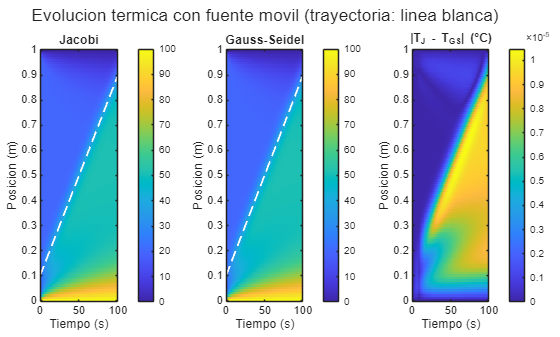

%% CODIGO 5. Figuras
% Se exportan con nombres nuevos para NO confundirlas con la Entrega 2.
carpeta = 'Resultados_Fuente_Movil';
if ~exist(carpeta,'dir'), mkdir(carpeta); end

limitesColor = [min([T_J(:);T_GS(:)]),max([T_J(:);T_GS(:)])];
f1 = figure('Name','Comparacion espacio-temporal','Color','w');
tiledlayout(1,3,'TileSpacing','compact','Padding','compact');
nexttile;
imagesc(t,x,T_J); axis xy; caxis(limitesColor); colorbar; hold on;
plot(t,xc(t),'w--','LineWidth',1.4);
xlabel('Tiempo (s)'); ylabel('Posicion (m)'); title('Jacobi');
nexttile;
imagesc(t,x,T_GS); axis xy; caxis(limitesColor); colorbar; hold on;
plot(t,xc(t),'w--','LineWidth',1.4);
xlabel('Tiempo (s)'); ylabel('Posicion (m)'); title('Gauss-Seidel');
nexttile;
imagesc(t,x,Diferencia_J_GS); axis xy; colorbar;
xlabel('Tiempo (s)'); ylabel('Posicion (m)'); title('|T_J - T_{GS}| (°C)');
sgtitle('Evolucion termica con fuente movil (trayectoria: linea blanca)');
exportgraphics(f1,fullfile(carpeta,'fig1_fuente_movil.png'),'Resolution',300);

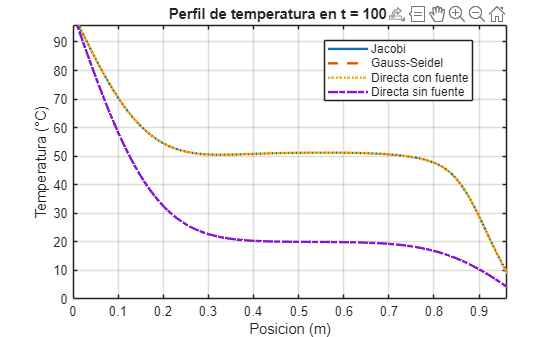


f2 = figure('Name','Perfil final','Color','w');
plot(x,T_J(:,end),'-','LineWidth',1.8); hold on;
plot(x,T_GS(:,end),'--','LineWidth',1.8);
plot(x,T_ref(:,end),':','LineWidth',1.8);
plot(x,T_sin(:,end),'-.','LineWidth',1.8);
grid on; xlabel('Posicion (m)'); ylabel('Temperatura (°C)');
title(sprintf('Perfil de temperatura en t = %.1f s',t_f));
legend('Jacobi','Gauss-Seidel','Directa con fuente','Directa sin fuente','Location','best');
exportgraphics(f2,fullfile(carpeta,'fig2_perfil_final_fuente.png'),'Resolution',300);

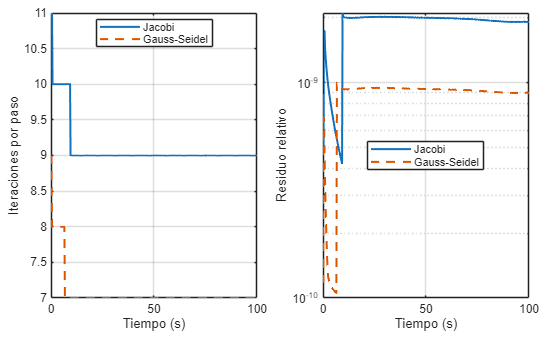


f3 = figure('Name','Convergencia de los solucionadores','Color','w');
tiledlayout(1,2,'TileSpacing','compact','Padding','compact');
nexttile;
plot(t(2:end),iter_J,'-','LineWidth',1.5); hold on;
plot(t(2:end),iter_GS,'--','LineWidth',1.5);
grid on; xlabel('Tiempo (s)'); ylabel('Iteraciones por paso');
legend('Jacobi','Gauss-Seidel','Location','best');
nexttile;
semilogy(t(2:end),max(resRel_J,eps),'-','LineWidth',1.5); hold on;
semilogy(t(2:end),max(resRel_GS,eps),'--','LineWidth',1.5);
grid on; xlabel('Tiempo (s)'); ylabel('Residuo relativo');
legend('Jacobi','Gauss-Seidel','Location','best');
exportgraphics(f3,fullfile(carpeta,'fig3_convergencia_fuente.png'),'Resolution',300);

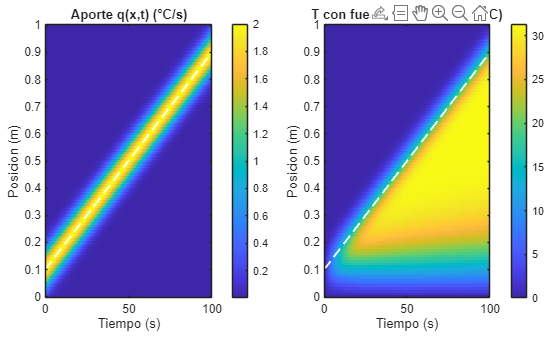


f4 = figure('Name','Efecto de la fuente','Color','w');
tiledlayout(1,2,'TileSpacing','compact','Padding','compact');
nexttile;
imagesc(t,x,q(x,t)); axis xy; colorbar; hold on;
plot(t,xc(t),'w--','LineWidth',1.4);
xlabel('Tiempo (s)'); ylabel('Posicion (m)'); title('Aporte q(x,t) (°C/s)');
nexttile;
imagesc(t,x,Incremento_fuente); axis xy; colorbar; hold on;
plot(t,xc(t),'w--','LineWidth',1.4);
xlabel('Tiempo (s)'); ylabel('Posicion (m)'); title('T con fuente - T sin fuente (°C)');
exportgraphics(f4,fullfile(carpeta,'fig4_efecto_fuente.png'),'Resolution',300);

## Código 6. Exportación de resultados del caso base

%% CODIGO 6. Exportacion de resultados
Parametros = table(L,alpha,T_0,T_L,T_R,t_f,N_x,N_t,dx,dt,r,Tol,Q0,sigma,x_s,v);
writetable(Parametros,fullfile(carpeta,'Parametros_Fuente.csv'));

Resumen = table(sum(iter_J),sum(iter_GS),tiempo_J,tiempo_GS,tiempo_ref, ...
    max(resRel_J),max(resRel_GS),maxDiferencia_J_GS,maxErrorRef_J,maxErrorRef_GS, ...
    maxT,maxIncremento,x(ix),t(it),errorFrontera, ...
    'VariableNames',{'IteracionesJacobi','IteracionesGaussSeidel','TiempoJacobi_s', ...
    'TiempoGaussSeidel_s','TiempoDirecto_s','ResiduoRelMaxJacobi','ResiduoRelMaxGaussSeidel', ...
    'DiferenciaMaxima_J_GS_C','DiferenciaMaxima_J_Directa_C','DiferenciaMaxima_GS_Directa_C', ...
    'TemperaturaMaxInterior_C','IncrementoMaxFuente_C','PosicionMaxIncremento_m', ...
    'TiempoMaxIncremento_s','ErrorFrontera_C'});
writetable(Resumen,fullfile(carpeta,'Resumen_Fuente.csv'));

MetricasTiempo = table(t(2:end)',iter_J,iter_GS,errorIter_J,errorIter_GS,resRel_J,resRel_GS, ...
    'VariableNames',{'Tiempo_s','IteracionesJacobi','IteracionesGaussSeidel', ...
    'CambioRelativoJacobi','CambioRelativoGaussSeidel','ResiduoRelativoJacobi','ResiduoRelativoGaussSeidel'});
writetable(MetricasTiempo,fullfile(carpeta,'Metricas_por_Paso.csv'));

Perfiles = table(x,T_J(:,end),T_GS(:,end),T_ref(:,end),T_sin(:,end),Incremento_fuente(:,end), ...
    'VariableNames',{'Posicion_m','TemperaturaJacobi_C','TemperaturaGaussSeidel_C', ...
    'TemperaturaDirecta_C','TemperaturaSinFuente_C','IncrementoFuente_C'});
writetable(Perfiles,fullfile(carpeta,'Perfil_Final.csv'));
save(fullfile(carpeta,'Simulacion_Fuente.mat'),'x','t','T_J','T_GS','T_ref','T_sin', ...
    'Incremento_fuente','Parametros','Resumen','MetricasTiempo');
fprintf('\nArchivos exportados en %s\n',carpeta);


Archivos exportados en Resultados_Fuente_Movil


## Código 7. Problema de validación con solución analítica

%% ETAPA 2. VALIDACION DE LOS ESQUEMAS DE DIFERENCIAS FINITAS
% Se usa la solucion directa para aislar el error de discretizacion.

%% CODIGO 7. Problema de validacion con solucion analitica
TL = T_L;
TR = T_R;
tf = t_f;
amplitud = 5;
m = 4;                         % modo de Fourier (entero)
omega = m*pi/L;
q0 = @(x,t) zeros(size(x));    % sin fuente para este ensayo
Tlineal = @(x) TL+(TR-TL)*x/L;
Tini = @(x) Tlineal(x)+amplitud*sin(omega*x);
Texacta = @(x,t) Tlineal(x)+amplitud*exp(-alpha*omega^2*t)*sin(omega*x);

carpeta_validacion = 'Resultados_Validacion';
if ~exist(carpeta_validacion,'dir'), mkdir(carpeta_validacion); end
fprintf('VALIDACION ANALITICA: CN Y EULER IMPLICITO\n');

VALIDACION ANALITICA: CN Y EULER IMPLICITO


fprintf('Modo de Fourier m = %d | Tiempo final = %.1f s\n\n',m,tf);

Modo de Fourier m = 4 | Tiempo final = 100.0 s



## Código 8. Orden espacial de Crank–Nicolson

%% CODIGO 8. Orden espacial de Crank-Nicolson
% dt pequeno y constante para que predomine el error espacial.
Nx_values = [21;41;81;161];
dt_fino = 0.05;
dx_values = L./(Nx_values-1);
E_CN_x = zeros(size(Nx_values));
for j = 1:numel(Nx_values)
    [xval,T_CN] = resolverCalor(L,alpha,TL,TR,tf,Nx_values(j),dt_fino,0.5,Tini,q0);
    E_CN_x(j) = max(abs(T_CN-Texacta(xval,tf)));
end
p_CN_x = [NaN; log2(E_CN_x(1:end-1)./E_CN_x(2:end))];
OrdenEspacial = table(Nx_values,dx_values,repmat(dt_fino,size(Nx_values)),E_CN_x,p_CN_x, ...
    'VariableNames',{'Nx','dx_m','dt_s','Error_CN_C','Orden_CN'});
disp('ORDEN ESPACIAL DE CRANK-NICOLSON');

ORDEN ESPACIAL DE CRANK-NICOLSON


disp(OrdenEspacial);

    Nx      dx_m      dt_s    Error_CN_C    Orden_CN
    ___    _______    ____    __________    ________

     21       0.05    0.05     0.051574         NaN 
     41      0.025    0.05      0.01343      1.9412 
     81     0.0125    0.05    0.0033495      2.0035 
    161    0.00625    0.05    0.0008368       2.001 



writetable(OrdenEspacial,fullfile(carpeta_validacion,'Orden_Espacial.csv'));



## Código 9. Orden temporal de ambos esquemas

%% CODIGO 9. Orden temporal de Crank-Nicolson y Euler implicito
% Se fija una malla muy fina para que predomine el error temporal.
Nx_fino = 3201;
dt_values = [20;10;5;2.5];
E_CN_t = zeros(size(dt_values));
E_EI_t = zeros(size(dt_values));
for j = 1:numel(dt_values)
    [xval,T_CN] = resolverCalor(L,alpha,TL,TR,tf,Nx_fino,dt_values(j),0.5,Tini,q0);
    [~,T_EI] = resolverCalor(L,alpha,TL,TR,tf,Nx_fino,dt_values(j),1,Tini,q0);
    T_ex = Texacta(xval,tf);
    E_CN_t(j) = max(abs(T_CN-T_ex));
    E_EI_t(j) = max(abs(T_EI-T_ex));
end
p_CN_t = [NaN; log2(E_CN_t(1:end-1)./E_CN_t(2:end))];
p_EI_t = [NaN; log2(E_EI_t(1:end-1)./E_EI_t(2:end))];
OrdenTemporal = table(dt_values,repmat(L/(Nx_fino-1),size(dt_values)), ...
    E_CN_t,p_CN_t,E_EI_t,p_EI_t, ...
    'VariableNames',{'dt_s','dx_m','Error_CN_C','Orden_CN','Error_Euler_C','Orden_Euler'});
disp('ORDEN TEMPORAL DE AMBOS ESQUEMAS');

ORDEN TEMPORAL DE AMBOS ESQUEMAS


disp(OrdenTemporal);

    dt_s      dx_m       Error_CN_C    Orden_CN    Error_Euler_C    Orden_Euler
    ____    _________    __________    ________    _____________    ___________

     20     0.0003125      0.013643        NaN        0.23682             NaN  
     10     0.0003125     0.0033875     2.0098        0.12324         0.94226  
      5     0.0003125    0.00084398      2.005       0.062913         0.97008  
    2.5     0.0003125    0.00020934     2.0113       0.031791         0.98474  



writetable(OrdenTemporal,fullfile(carpeta_validacion,'Orden_Temporal.csv'));



## Código 10. Comparación con fuente móvil y referencia refinada

%% CODIGO 10. Comparacion con fuente movil y referencia refinada
% Mismos parametros y condiciones iniciales de la etapa 1.
T0fuente = @(x) T_0*ones(size(x));
Nx_base = N_x;
dt_base = dt;
[xb,TCN] = resolverCalor(L,alpha,TL,TR,tf,Nx_base,dt_base,0.5,T0fuente,q);
[~,TEI] = resolverCalor(L,alpha,TL,TR,tf,Nx_base,dt_base,1,T0fuente,q);

% Dos refinamientos anidados de CN para contrastar la referencia.
[xr1,Tr1] = resolverCalor(L,alpha,TL,TR,tf,801,0.03125,0.5,T0fuente,q);
[xr2,Tr2] = resolverCalor(L,alpha,TL,TR,tf,1601,0.015625,0.5,T0fuente,q);
% Las mallas son anidadas: no se introduce error de interpolacion.
Tref = Tr2(1:16:end);
Tref_fina = Tr2(1:2:end);
assert(max(abs(xb-xr2(1:16:end)))<1e-12,'Mallas no coincidentes');
assert(max(abs(xr1-xr2(1:2:end)))<1e-12,'Referencias no coincidentes');
Eref = max(abs(Tr1-Tref_fina));
E_CN_fuente = max(abs(TCN-Tref));
E_EI_fuente = max(abs(TEI-Tref));
fprintf('COMPARACION DE ESQUEMAS CON FUENTE MOVIL (t = %.0f s)\n',tf);

COMPARACION DE ESQUEMAS CON FUENTE MOVIL (t = 100 s)


fprintf('Error maximo CN respecto a referencia fina: %.8e °C\n',E_CN_fuente);

Error maximo CN respecto a referencia fina: 1.23737250e-02 °C


fprintf('Error maximo Euler implicito:                %.8e °C\n',E_EI_fuente);

Error maximo Euler implicito:                2.30164123e-01 °C


fprintf('Diferencia entre referencias refinadas:      %.8e °C\n\n',Eref);

Diferencia entre referencias refinadas:      1.45539194e-04 °C



ComparacionFuente = table(Nx_base,dt_base,E_CN_fuente,E_EI_fuente,Eref);
writetable(ComparacionFuente,fullfile(carpeta_validacion,'Comparacion_Esquemas_Fuente.csv'));
Perfiles = table(xb,TCN,TEI,Tref,abs(TCN-Tref),abs(TEI-Tref), ...
    'VariableNames',{'Posicion_m','CrankNicolson_C','EulerImplicito_C','ReferenciaFina_C','Error_CN_C','Error_Euler_C'});
writetable(Perfiles,fullfile(carpeta_validacion,'Perfiles_Fuente.csv'));



## Código 11. Gráficas de validación y comparación

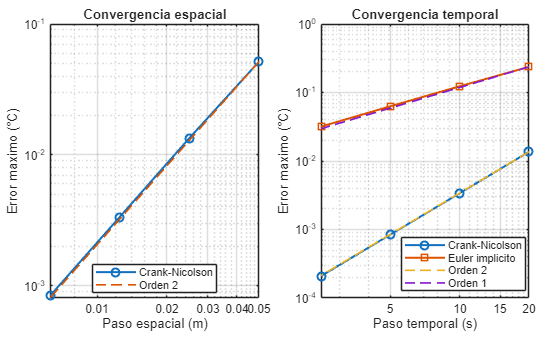

%% CODIGO 11. Graficas de validacion y comparacion
f5 = figure('Name','Orden de convergencia','Color','w');
tiledlayout(1,2,'TileSpacing','compact','Padding','compact');
nexttile;
loglog(dx_values,E_CN_x,'-o','LineWidth',1.5); hold on;
loglog(dx_values,E_CN_x(1)*(dx_values/dx_values(1)).^2,'--','LineWidth',1.2);
grid on; xlabel('Paso espacial (m)'); ylabel('Error maximo (°C)');
title('Convergencia espacial'); legend('Crank-Nicolson','Orden 2','Location','best');
nexttile;
loglog(dt_values,E_CN_t,'-o','LineWidth',1.5); hold on;
loglog(dt_values,E_EI_t,'-s','LineWidth',1.5);
loglog(dt_values,E_CN_t(1)*(dt_values/dt_values(1)).^2,'--','LineWidth',1.2);
loglog(dt_values,E_EI_t(1)*(dt_values/dt_values(1)),'--','LineWidth',1.2);
grid on; xlabel('Paso temporal (s)'); ylabel('Error maximo (°C)');
title('Convergencia temporal');
legend('Crank-Nicolson','Euler implicito','Orden 2','Orden 1','Location','best');
exportgraphics(f5,fullfile(carpeta_validacion,'fig5_orden_convergencia.png'),'Resolution',300);

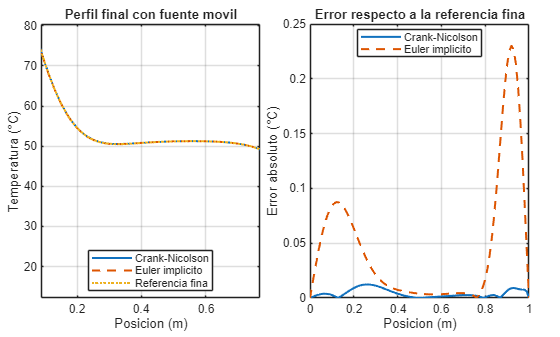


f6 = figure('Name','Comparacion con fuente movil','Color','w');
tiledlayout(1,2,'TileSpacing','compact','Padding','compact');
nexttile;
plot(xb,TCN,'-','LineWidth',1.5); hold on;
plot(xb,TEI,'--','LineWidth',1.5);
plot(xb,Tref,':','LineWidth',1.5);
grid on; xlabel('Posicion (m)'); ylabel('Temperatura (°C)');
title('Perfil final con fuente movil');
legend('Crank-Nicolson','Euler implicito','Referencia fina','Location','best');
nexttile;
plot(xb,abs(TCN-Tref),'-','LineWidth',1.5); hold on;
plot(xb,abs(TEI-Tref),'--','LineWidth',1.5);
grid on; xlabel('Posicion (m)'); ylabel('Error absoluto (°C)');
title('Error respecto a la referencia fina');
legend('Crank-Nicolson','Euler implicito','Location','best');
exportgraphics(f6,fullfile(carpeta_validacion,'fig6_comparacion_esquemas.png'),'Resolution',300);


fprintf('Resultados exportados en %s\n',carpeta_validacion);

Resultados exportados en Resultados_Validacion


## Código 12. Sensibilidad física de la fuente móvil

%% CODIGO 12. Sensibilidad fisica de la fuente movil
% Se cambia un parametro a la vez, manteniendo la malla y el resto de
% parametros del caso base. Se usa CN con solucion directa para aislar
% el efecto de los parametros fisicos del error del solucionador iterativo.
carpeta_sensibilidad = 'Resultados_Sensibilidad';
if ~exist(carpeta_sensibilidad,'dir'), mkdir(carpeta_sensibilidad); end
Q_values = [1;2;3];             % °C/s
v_values = [0.004;0.006;0.008]; % m/s
assert(all(x_s+v_values*tf<=L) && all(x_s+v_values*tf>=0), ...
    'La trayectoria de alguna fuente sale de la barra.');

% Temperatura adicional respecto al mismo problema sin fuente, en t=tf.
Tsin_final = T_sin(:,end);
Incrementos_Q = zeros(Nx_base,numel(Q_values));
Incrementos_v = zeros(Nx_base,numel(v_values));
Max_Q = zeros(size(Q_values)); Pos_Q = Max_Q; Media_Q = Max_Q;
Max_v = zeros(size(v_values)); Pos_v = Max_v; Media_v = Max_v;

for j = 1:numel(Q_values)
    q_intensidad = @(xx,tt) Q_values(j)*exp(-(xx-(x_s+v*tt)).^2/(2*sigma^2));
    [xsens,T_Q] = resolverCalor(L,alpha,TL,TR,tf,Nx_base,dt_base,0.5,T0fuente,q_intensidad);
    Incrementos_Q(:,j) = T_Q-Tsin_final;
    [Max_Q(j),idx_Q] = max(Incrementos_Q(:,j));
    Pos_Q(j) = xsens(idx_Q);
    Media_Q(j) = mean(Incrementos_Q(2:end-1,j));
end

for j = 1:numel(v_values)
    q_velocidad = @(xx,tt) Q0*exp(-(xx-(x_s+v_values(j)*tt)).^2/(2*sigma^2));
    [xsens,T_v] = resolverCalor(L,alpha,TL,TR,tf,Nx_base,dt_base,0.5,T0fuente,q_velocidad);
    Incrementos_v(:,j) = T_v-Tsin_final;
    [Max_v(j),idx_v] = max(Incrementos_v(:,j));
    Pos_v(j) = xsens(idx_v);
    Media_v(j) = mean(Incrementos_v(2:end-1,j));
end

assert(max(abs(xsens-x))<1e-12,'Mallas no coincidentes en sensibilidad');
% La fuente entra linealmente a la ecuacion: con velocidad fija, el
% incremento termico debe ser proporcional a Q0.
assert(max(abs(Incrementos_Q(:,2)-2*Incrementos_Q(:,1)))<1e-7, ...
    'La prueba de linealidad de la fuente no se cumplio');
assert(max(abs(Incrementos_Q(:,3)-3*Incrementos_Q(:,1)))<1e-7, ...
    'La prueba de linealidad de la fuente no se cumplio');
% Verificar que los casos base de ambos barridos reproducen la simulacion.
idx_base_Q = find(abs(Q_values-Q0)<1e-12,1);
idx_base_v = find(abs(v_values-v)<1e-12,1);
if ~isempty(idx_base_Q)
    assert(max(abs(Incrementos_Q(:,idx_base_Q)-Incremento_fuente(:,end)))<1e-7, ...
        'El barrido de intensidad no reprodujo el caso base');
end
if ~isempty(idx_base_v)
    assert(max(abs(Incrementos_v(:,idx_base_v)-Incremento_fuente(:,end)))<1e-7, ...
        'El barrido de velocidad no reprodujo el caso base');
end

SensQ = table(Q_values,repmat(v,size(Q_values)),Max_Q,Pos_Q,Media_Q, ...
    'VariableNames',{'Q0_C_s','Velocidad_m_s','IncrementoMaxFinal_C','PosicionMax_m','IncrementoMedioInterior_C'});
SensV = table(v_values,repmat(Q0,size(v_values)),x_s+v_values*tf,Max_v,Pos_v,Media_v, ...
    'VariableNames',{'Velocidad_m_s','Q0_C_s','CentroFuenteFinal_m','IncrementoMaxFinal_C','PosicionMax_m','IncrementoMedioInterior_C'});
disp('SENSIBILIDAD A LA INTENSIDAD DE LA FUENTE (t = tf)'); disp(SensQ);

SENSIBILIDAD A LA INTENSIDAD DE LA FUENTE (t = tf)
    Q0_C_s    Velocidad_m_s    IncrementoMaxFinal_C    PosicionMax_m    IncrementoMedioInterior_C
    ______    _____________    ____________________    _____________    _________________________

      1           0.008               15.665                0.7                  12.004          
      2           0.008               31.331                0.7                  24.008          
      3           0.008               46.996                0.7                  36.011          



disp('SENSIBILIDAD A LA VELOCIDAD DE LA FUENTE (t = tf)'); disp(SensV);

SENSIBILIDAD A LA VELOCIDAD DE LA FUENTE (t = tf)
    Velocidad_m_s    Q0_C_s    CentroFuenteFinal_m    IncrementoMaxFinal_C    PosicionMax_m    IncrementoMedioInterior_C
    _____________    ______    ___________________    ____________________    _____________    _________________________

        0.004          2               0.5                   59.803                0.4                  23.102          
        0.006          2               0.7                   41.664               0.55                  23.716          
        0.008          2               0.9                   31.331                0.7                  24.008          



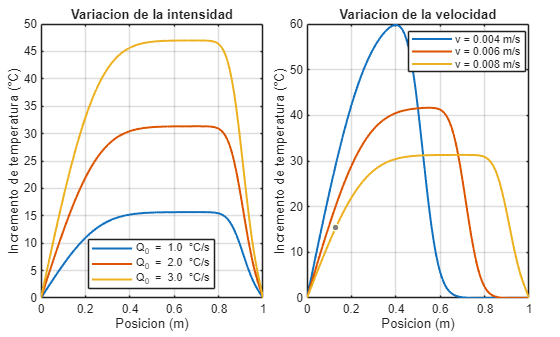

writetable(SensQ,fullfile(carpeta_sensibilidad,'Sensibilidad_Intensidad.csv'));
writetable(SensV,fullfile(carpeta_sensibilidad,'Sensibilidad_Velocidad.csv'));

f7 = figure('Name','Sensibilidad de la fuente movil','Color','w');
tiledlayout(1,2,'TileSpacing','compact','Padding','compact');
nexttile;
plot(xsens,Incrementos_Q,'LineWidth',1.5);
grid on; xlabel('Posicion (m)'); ylabel('Incremento de temperatura (°C)');
title('Variacion de la intensidad');
legend(compose('Q_0 = %.1f °C/s',Q_values),'Location','best');
nexttile;
plot(xsens,Incrementos_v,'LineWidth',1.5);
grid on; xlabel('Posicion (m)'); ylabel('Incremento de temperatura (°C)');
title('Variacion de la velocidad');
legend(compose('v = %.3f m/s',v_values),'Location','best');
exportgraphics(f7,fullfile(carpeta_sensibilidad,'fig7_sensibilidad_fuente.png'),'Resolution',300);

## Código 13. Mediciones repetidas del tiempo de ejecución

%% CODIGO 13. Comparacion temporal reproducible de Jacobi y Gauss-Seidel
% Se construye una secuencia identica de sistemas lineales para ambos
% metodos, usando el estado CN directo del paso anterior como x0 y para b.
% No se incluyen ensamblaje, graficas, ni exportacion en las mediciones.
carpeta_tiempos = 'Resultados_Tiempos';
if ~exist(carpeta_tiempos,'dir'), mkdir(carpeta_tiempos); end
X0_medicion = T_ref(2:end-1,1:N_t);
B_medicion = zeros(n,N_t);
for k = 1:N_t
    aporte_medicion = (dt/2)*(q(xi,t(k))+q(xi,t(k+1)));
    B_medicion(:,k) = B*X0_medicion(:,k)+frontera+aporte_medicion;
end

nrep = 7;
tiempos_rep = zeros(nrep,2);
metodos_tiempo = {@jacobi,@gausseidel};
% Una pasada completa de calentamiento no se registra. En las siete
% repeticiones se alterna el orden para reducir el sesgo de ejecucion.
for rep = 0:nrep
    if mod(rep,2)==0
        orden_tiempo = [1,2];
    else
        orden_tiempo = [2,1];
    end
    for metodo = orden_tiempo
        solver = metodos_tiempo{metodo};
        reloj = tic;
        for k = 1:N_t
            z_medicion = solver(A,B_medicion(:,k),X0_medicion(:,k),Tol);
        end
        duracion = toc(reloj);
        if rep>0
            tiempos_rep(rep,metodo) = duracion;
        end
    end
end

assert(all(isfinite(tiempos_rep(:))) && all(tiempos_rep(:)>0), ...
    'Medicion temporal no valida');
Repeticiones = table((1:nrep)',tiempos_rep(:,1),tiempos_rep(:,2), ...
    'VariableNames',{'Repeticion','Jacobi_s','GaussSeidel_s'});
ResumenTiempos = table(["Jacobi";"Gauss-Seidel"],median(tiempos_rep,1)', ...
    min(tiempos_rep,[],1)',max(tiempos_rep,[],1)',std(tiempos_rep,0,1)', ...
    'VariableNames',{'Metodo','Mediana_s','Minimo_s','Maximo_s','DesviacionEstandar_s'});
Entorno = table(string(version),string(computer),N_x,N_t,Tol,nrep, ...
    'VariableNames',{'VersionMATLAB','Plataforma','NodosEspaciales','PasosTemporales','Tolerancia','Repeticiones'});
disp('TIEMPOS PARA SISTEMAS Y APROXIMACIONES INICIALES IDENTICOS'); disp(Repeticiones);

TIEMPOS PARA SISTEMAS Y APROXIMACIONES INICIALES IDENTICOS
    Repeticion    Jacobi_s    GaussSeidel_s
    __________    ________    _____________

        1         0.038632      0.052478   
        2         0.038723      0.054604   
        3          0.03653      0.052962   
        4         0.036724      0.048095   
        5         0.037978       0.05236   
        6         0.039264      0.048807   
        7         0.030336      0.042765   



disp(ResumenTiempos); disp(Entorno);

        Metodo        Mediana_s    Minimo_s    Maximo_s    DesviacionEstandar_s
    ______________    _________    ________    ________    ____________________

    "Jacobi"          0.037978     0.030336    0.039264         0.0030638      
    "Gauss-Seidel"     0.05236     0.042765    0.054604         0.0040509      

          VersionMATLAB          Plataforma    NodosEspaciales    PasosTemporales    Tolerancia    Repeticiones
    _________________________    __________    _______________    _______________    __________    ____________

    "25.2.0.2998904 (R2025b)"    "PCWIN64"           101                400    

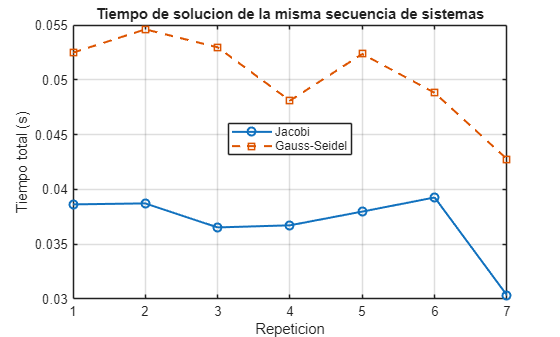

writetable(Repeticiones,fullfile(carpeta_tiempos,'Tiempos_Repeticiones.csv'));
writetable(ResumenTiempos,fullfile(carpeta_tiempos,'Resumen_Tiempos.csv'));
writetable(Entorno,fullfile(carpeta_tiempos,'Entorno_Medicion.csv'));

f8 = figure('Name','Mediciones repetidas del tiempo','Color','w');
plot(1:nrep,tiempos_rep(:,1),'-o','LineWidth',1.5); hold on;
plot(1:nrep,tiempos_rep(:,2),'--s','LineWidth',1.5);
grid on; xticks(1:nrep); xlabel('Repeticion'); ylabel('Tiempo total (s)');
title('Tiempo de solucion de la misma secuencia de sistemas');
legend('Jacobi','Gauss-Seidel','Location','best');
exportgraphics(f8,fullfile(carpeta_tiempos,'fig8_tiempos_repetidos.png'),'Resolution',300);


fprintf('\nAnalisis adicionales exportados en %s y %s.\n',carpeta_sensibilidad,carpeta_tiempos);


Analisis adicionales exportados en Resultados_Sensibilidad y Resultados_Tiempos.


## Función auxiliar de los esquemas theta

%% FUNCION AUXILIAR. Familia de esquemas theta
% theta=0.5: Crank-Nicolson; theta=1: Euler implicito (BTCS).
% A se factoriza una vez. El solucionador directo permite evaluar el esquema
% sin introducir el error de parada de Jacobi o Gauss-Seidel.
function [x,T] = resolverCalor(L,alpha,TL,TR,tf,Nx,dt,theta,Tini,q)
    x = linspace(0,L,Nx)';
    xi = x(2:end-1);
    dx = x(2)-x(1);
    Nt = round(tf/dt);
    dt = tf/Nt;
    r = alpha*dt/dx^2;
    n = Nx-2;
    e = ones(n,1);
    A = spdiags([-theta*r*e,(1+2*theta*r)*e,-theta*r*e],[-1,0,1],n,n);
    B = spdiags([(1-theta)*r*e,(1-2*(1-theta)*r)*e,(1-theta)*r*e],[-1,0,1],n,n);
    frontera = zeros(n,1);
    frontera(1) = frontera(1)+r*TL;
    frontera(end) = frontera(end)+r*TR;
    F = decomposition(A,'chol');
    u = Tini(xi);
    qn = q(xi,0);
    for k = 1:Nt
        qnext = q(xi,k*dt);
        aporte = dt*((1-theta)*qn+theta*qnext);
        u = F\(B*u+frontera+aporte);
        qn = qnext;
    end
    T = [TL;u;TR];
    assert(all(isfinite(T)),'Temperatura no finita');
end



## Funciones originales de la plantilla

%% FUNCIONES ORIGINALES (sin modificaciones)
function [z] = jacobi(A, b, x0, Tol)
    D = diag(diag(A));
    L = -tril(A, -1);
    U = -triu(A, 1);
    Tj = inv(D) * (L + U);
    cj = inv(D) * b;
    error = 1;
    z = [x0' error];
    while error > Tol
        x1 = Tj * x0 + cj;
        error = norm(x1 - x0, inf) / norm(x1, inf);
        z = [z; x1' error];
        x0 = x1;
    end
end

function [z] = gausseidel(A, b, x0, Tol)
    D = diag(diag(A));
    L = -tril(A, -1);
    U = -triu(A, 1);
    Tgs = inv(D - L) * U;
    cgs = inv(D - L) * b;
    error = 1;
    z = [x0' error];
    while error > Tol
        x1 = Tgs * x0 + cgs;
        error = norm(x1 - x0, 'inf') / norm(x1, 'inf');
        z = [z; x1' error];
        x0 = x1;
    end
end

function op = diagdom(A)
    [m,n] = size(A);
    op = 1;
    if m == n
        for k = 1:m
            if abs(A(k,k)) <= sum(abs(A(k,:))) - abs(A(k,k))
                op = 0;
                break;
            end
        end
    end
end
